% Q: remove leakage

% none
m = zeros(1024,1);
ol.setColumn1024(m)
s0 = cs.measure;

vciex = 0.4028

vciey = 0.4105

vy = 0.0992


% all
m = ones(1024,1)*40000;
ol.setColumn1024(m)
sall = cs.measure;

vciex = 0.3652

vciey = 0.4100

vy = 12.7670


return



% Q: what is the minimum column gap to generate discernable outputs?

col_1 = 500;
gap = 75;

% left
m = zeros(1024,1);
m(col_1) = 40000;
ol.setColumn1024(m)
s1 = cs.measure;

% right
m = zeros(1024,1);
m(col_1+gap) = 40000;
ol.setColumn1024(m)
s2 = cs.measure;

% both
m = zeros(1024,1);
m(col_1) = 40000;
m(col_1+gap) = 40000;
ol.setColumn1024(m)
s12 = cs.measure;

% view
clf
hold on
s1.plot
s2.plot

return

% Q: will two consecuitive columns generate discernable outputs?

col_1 = 500;
gap = 1;

% left
m = zeros(1024,1);
m(col_1) = 40000;
ol.setColumn1024(m)
s1 = cs.measure;

vciex = 0.4085

vciey = 0.4518

vy = 0.1476


% right
m = zeros(1024,1);
m(col_1+gap) = 40000;
ol.setColumn1024(m)
s2 = cs.measure;

vciex = 0.4092

vciey = 0.4513

vy = 0.1476


% both
m = zeros(1024,1);
m(col_1) = 40000;
m(col_1+gap) = 40000;
ol.setColumn1024(m)
s12 = cs.measure;

vciex = 0.4124

vciey = 0.4760

vy = 0.1955


% none
m = zeros(1024,1);
ol.setColumn1024(m)
s0 = cs.measure;

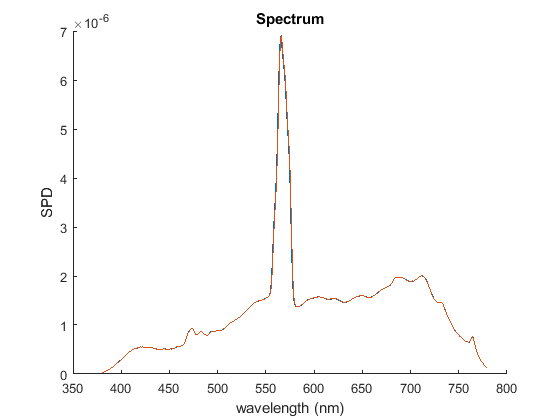


% view
clf
hold on
s1.plot
s2.plot


return


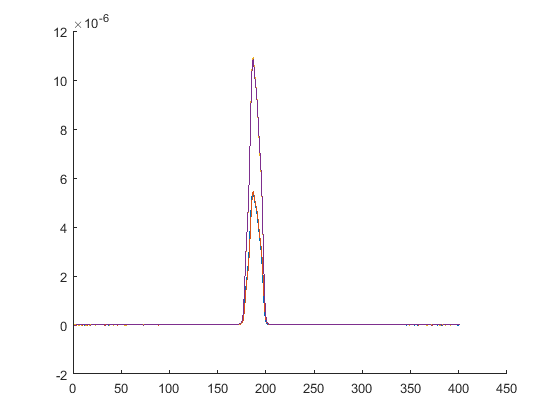


t0 = s0.amplitude;
t1 = s1.amplitude - t0;
t2 = s2.amplitude - t0;
t12 = s12.amplitude - t0;

clf
hold on
plot(t1)
plot(t2)
plot(t12)
plot(t1+t2)


return

% Q: what are the independent spikes?

gap = 75;
max_val = 40000;

col_start = 1;
m = zeros(1024,1);
for col_1 = col_start:gap:1024
    m(col_1) = max_val;
end

ol.setColumn1024(m)
s75_1 = cs.measure;

Yxy =     0.2502    0.3791    0.4115



col_start = 25;
m = zeros(1024,1);
for col_1 = col_start:gap:1024
    m(col_1) = max_val;
end

ol.setColumn1024(m)
s75_25 = cs.measure;

Yxy =     0.2486    0.3788    0.4091



col_start = 49;
m = zeros(1024,1);
for col_1 = col_start:gap:1024
    m(col_1) = max_val;
end

ol.setColumn1024(m)
s75_49 = cs.measure;

Yxy =     0.2484    0.3793    0.4102




t75_1 = s75_1.amplitude - s0.amplitude;
t75_25 = s75_25.amplitude - s0.amplitude;
t75_49 = s75_49.amplitude - s0.amplitude;

% all columns on
max_val = 40000;

m = ones(1024,1)*max_val;

ol.setColumn1024(m)
sall = cs.measure;

Yxy =    11.6360    0.3653    0.4102


tall = sall.amplitude - s0.amplitude;

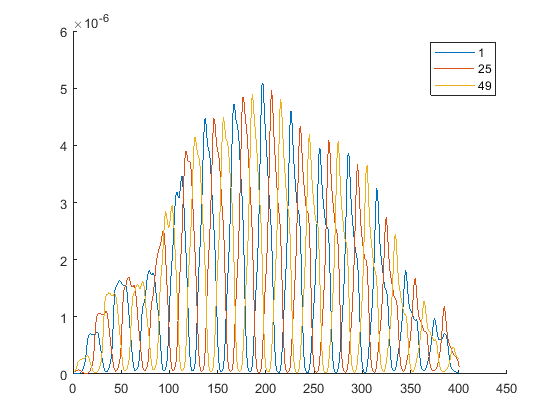


clf
hold on
plot(t75_1)
plot(t75_25)
plot(t75_49)
legend('1','25','49')

%plot(tall)

% saveas(gcf,'spike14_once.png')

return

1: has 13 spikes

25: has 13 spikes

49: has 14 spikes (left)


% Q: what are the independent (disjoint) spikes? Check additivity

gap = 75;

k = 0;
for col_1 = 1:gap:1024
    m = zeros(1024,1);
    m(col_1) = 40000;
    ol.setColumn1024(m)

    k = k + 1;
    sa(k) = cs.measure;
end

vciex = 0.4026

vciey = 0.4104

vy = 0.1006

vciex = 0.4017

vciey = 0.4088

vy = 0.1006

vciex = 0.3741

vciey = 0.3614

vy = 0.1008

vciex = 0.3619

vciey = 0.3504

vy = 0.1019

vciex = 0.3628

vciey = 0.3938

vy = 0.1091

vciex = 0.3549

vciey = 0.4676

vy = 0.1336

vciex = 0.3766

vciey = 0.4773

vy = 0.1517

vciex = 0.4269

vciey = 0.4353

vy = 0.1450

vciex = 0.4595

vciey = 0.3960

vy = 0.1254

vciex = 0.4348

vciey = 0.3976

vy = 0.1084

vciex = 0.4102

vciey = 0.4073

vy = 0.1020

vciex = 0.4036

vciey = 0.4101

vy = 0.1005

vciex = 0.4028

vciey = 0.4105

vy = 0.1004

vciex = 0.4027

vciey = 0.4105

vy = 0.1004


return

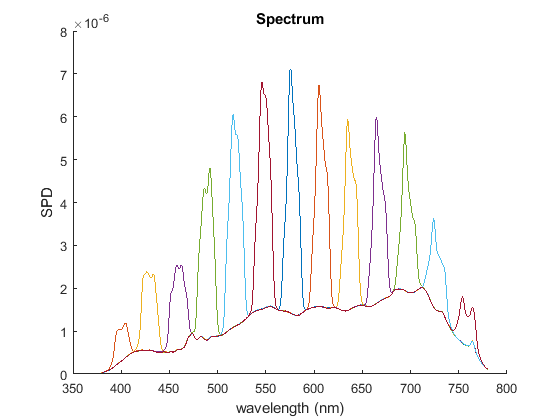

clf
hold on
for i=1:14
    sa(i).plot
end
saveas(gcf,'spike14.png')

return


% get the measurement data
load('spd_10_spikes','spd_10_spikes')

% the 10 spikes manually found
wl10 = [409 448 491 528 567 606 646 685 724 764];

% convert to index
wl10idx = wl10 - 380 + 1;

% get the amplitude
amp10 = spd_10_spikes(wl10idx);

% visualize
% plot(amp10,'o')


%
% adjust
%
n = ones(10,1);
n(1) = 100;
n(2) = 100;
n(3) = 100;
n(4) = 100;
n(5) = 44;
n(6) = 100;
n(7) = 100;
n(8) = 0;
n(9) = 100;
n(10) = 0;

%
% smooth
%
col_array = [100:100:1000];
m = interp1(col_array,n,1:1024,'spline');

%
% lit
%
ol.setColumn1024(m)

%
% measure
%
s = cs.measure;

vciex = 0.3627

vciey = 0.4044

vy = 164.8500

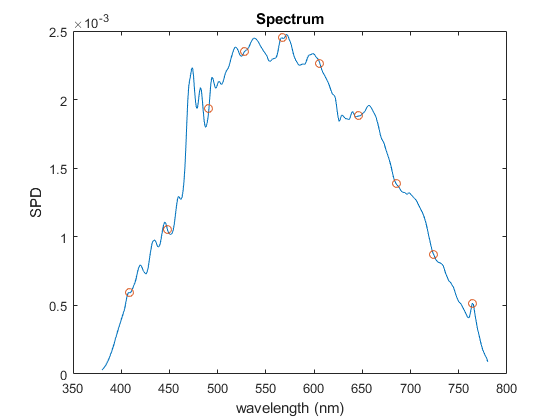


clf
s.plot;

%
% overlay the control points
%
hold on
a = s.amplitude;
a = a(wl10idx);
plot(wl10,a,'o')


return


% fat spike additivity
tab = zeros(25,3);

hw = 10;

col = 500

col = 500

col_1 = col-hw;
col_2 = col+hw;
col_1 = max(1,col_1);
col_2 = min(1024,col_2);
m = zeros(1024,1);
m(col_1:col_2) = 40000;
ol.setColumn1024(m)
s1 = cs.measure;

vciex = 0.4227

vciey = 0.5520

vy = 1.0165


col = 500+20

col = 520

col_1 = col-hw;
col_2 = col+hw;
col_1 = max(1,col_1);
col_2 = min(1024,col_2);
m = zeros(1024,1);
m(col_1:col_2) = 40000;
ol.setColumn1024(m)
s2 = cs.measure;

vciex = 0.4695

vciey = 0.5067

vy = 0.9737


m = zeros(1024,1);
ol.setColumn1024(m)
s0 = cs.measure;

vciex = 0.4028

vciey = 0.4107

vy = 0.0952


col = 500

col = 500

col_1 = col-hw;
col_2 = col+hw;
col_1 = max(1,col_1);
col_2 = min(1024,col_2);
m = zeros(1024,1);
m(col_1:col_2) = 40000;
col = 500+20

col = 520

col_1 = col-hw;
col_2 = col+hw;
col_1 = max(1,col_1);
col_2 = min(1024,col_2);
m(col_1:col_2) = 40000;
ol.setColumn1024(m)
s12 = cs.measure;

vciex = 0.4495

vciey = 0.5361

vy = 1.8556


return

tab = zeros(25,3);

hw = 10;

m = zeros(1024,1);

for col = [100:100:1000]
    col_1 = col-hw;
    col_2 = col+hw;
    col_1 = max(1,col_1);
    col_2 = min(1024,col_2);
    m(col_1:col_2) = 40000;
end


ol.setColumn1024(m)

s = cs.measure;

Index exceeds the number of array elements (4).

Error in cs2000Class/measure (line 55)
            if (err(1:5)=='OK00,')

s.plot;

return

[amp wlidx] = max(s.amplitude);
wlmax = 380 + wlidx - 1;

[col wlmax amp]
k = k + 1;
tab(k,1:3) = [col wlmax amp];


tab = tab(1:k,:);
tab
bar(tab(:,2),tab(:,3))